# **Constructing and evaluating the Rocket Equation**

Analysis and application of the rocket equation

## **Velocity as a function of time v(t)**

#### Declare and initialize variables

warning('off');
M0 =2800000;           % Inital Mass (kg)
m = 28000;           % Payload Mass (kg)
R = 25000;             % Mass Expulsion Rate (kg/s)
U = 2200   ;              % Relative Velocity (m/s)
g = 9.81;               % Force gravity (m/s^2)

### **Calculating Velocity**

#### Variables


$$\begin{array}{l}
m_t =M_0 +m\\
F=-g\left(M_0 +m-\mathrm{Rt}\right)
\end{array}$$


#### Substitute Variables


$$\begin{array}{l}
\left(m_t -\mathrm{Rt}\right)\frac{dv}{dt}=F+RU\\
\left(M_0 +m-Rt\right)\frac{dv}{dt}=-g\left(M_0 +m-\mathrm{Rt}\right)+RU
\end{array}$$


#### Solve for *dv *


$$\begin{array}{l}
\frac{\textrm{dv}}{\textrm{dt}}=\frac{\left(-g\left(M_0 +m-\textrm{Rt}\right)+\textrm{RU}\right)}{\left(M_0 +m-\textrm{Rt}\right)}\\
\textrm{dv}=-g+\frac{\textrm{RU}}{M_0 +m-\textrm{Rt}}\;\textrm{dt}
\end{array}$$


#### Integrate both sides to get *v(t)*


$$\begin{array}{l}
dv=\int \left(-g+\frac{RU}{M_0 +m-Rt}\right)\;dt\\
v\left(t\right)=-gt-U\cdot \ln \left(M_0 +m-Rt\right)+C
\end{array}$$


#### Determine the constant (using initial conditions)


$$\begin{array}{l}
v\left(0\right)=0-U\cdot \ln \left(M_0 +m\right)+C\\
C=U\cdot \ln \left(M_0 +m\right)\;
\end{array}$$
 

#### Formulate final equation


$$\;v\left(t\right)=-\textrm{gt}+U\cdot \;\ln \left(\frac{M_0 +m}{M_0 +m-\textrm{Rt}}\right)$$
    

### Velocity Calculation

t = 60;                % Time (s)
v = -g.*t+U.*(log((M0+m)./(M0+m-R.*t)))        % Velocity (m/s)

v = 1.0744e+03

## Displacement as a function of time x(t)

#### Integrate the function for velocity to find displacement


$$\begin{array}{l}
\textrm{dx}=\int \left(\left(-\textrm{gt}+U\cdot \;\ln \left(\frac{M_0 +m}{M_0 +m-\textrm{Rt}}\right)\right.\right)\textrm{dt}\begin{array}{l}
\\
\;\\

\end{array}\\
\textrm{dx}=\int \left(-\textrm{gt}+U\cdot \;\ln \left(M_0 +m\right)-U\cdot \ln \left(M_0 +m-\textrm{Rt}\right)\right)\textrm{dt}\begin{array}{l}
\\
\;\\

\end{array}\\
\textrm{Assume}\;\textrm{that}\;y=M_0 +m-\textrm{Rt},\textrm{then}\;\frac{\textrm{dy}}{\textrm{dt}}=-R\;\textrm{and}\;\textrm{dt}=-\frac{\textrm{dy}}{R}\\
\int \ln \left(M_0 +m-\textrm{Rt}\right)\cdot \textrm{dt}=-\frac{1}{R}\int \ln \left(y\right)\cdot \;\textrm{dy}=-\frac{1}{R}\left(y\cdot \ln \left(y\right)-y\right)=-\frac{M_0 +m-\textrm{Rt}}{R}\left(\ln \left(M_0 +m-\textrm{Rt}\right)-1\right)\;\\
x=\frac{-{\textrm{gt}}^2 }{2}+\textrm{Ut}\cdot \ln \left(M_0 +m\right)+\frac{U\left(M_0 +m-\textrm{Rt}\right)}{R}\left(\ln \left(M_0 +m-\textrm{Rt}\right)-1\right)+C
\end{array}$$


#### Determine the constant (using initial conditions)


$$\begin{array}{l}
x\left(0\right)=0\\
0=\frac{U\left(M_0 +m\right)}{R}\left(\ln \left(M_0 +m\right)-1\right)+C\\
C=-\;\frac{U\left(M_0 +m\right)}{R}\left(\ln \left(M_0 +m\right)-1\right)
\end{array}$$


#### Formulate final equation

$x\left(t\right)=\frac{-{\textrm{gt}}^2 }{2}+\textrm{Ut}\cdot \ln \left(M_0 +m\right)+\frac{U\left(M_0 +m-\textrm{Rt}\right)}{R}\cdot \;\left(\ln \left(M_0 +m-\textrm{Rt}\right)-1\right)$- $\frac{U\left(M_0 +m\right)}{R}\left(\ln \left(M_0 +m\right)-1\right)$

### Displacement Calculation

t = 0;   % Time (s)
x = (-g.*t.^2)./2+U.*t.*log(M0+m)+((U.*(M0+m-R.*t))./R).*(log(M0+m-R.*t)-1)-(U.*(M0+m)./R).*(log(M0+m)-1)

x = 0

## Graphing v(t) and x(t)

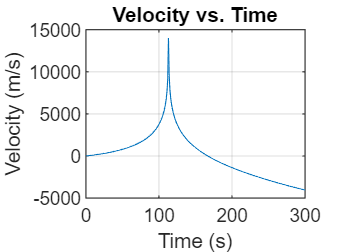

t = 0:300;
v = -g.*t+U*(log((M0+m)./(M0+m-R.*t)));
plot(t, v)
xlabel("Time (s)");
ylabel("Velocity (m/s)");
title("Velocity vs. Time");
grid on;

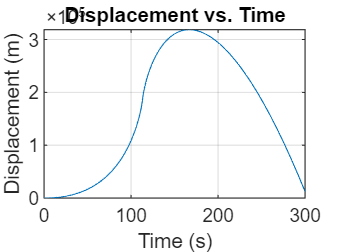


figure(2)
x = (-g.*t.^2)./2+U.*t.*log(M0+m)+((U.*(M0+m-R.*t))./R).*(log(M0+m-R.*t)-1)-(U.*(M0+m)./R).*(log(M0+m)-1);
plot(t, x)
xlabel("Time (s)");
ylabel("Displacement (m)");
title("Displacement vs. Time");
grid on;